# Magnetic vector potential from a current loop 

#### 
$${\displaystyle {\mathbf {A}}({\mathbf {r}})={\frac {\mu _{0}I}{4\pi }}
\int \frac { d \mathbf s}{|{\mathbf {r}}-{\mathbf {s}}|}}
$$


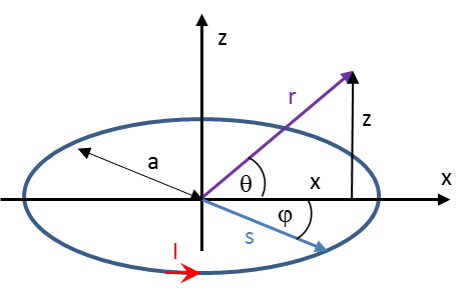

Due to symmetry it is sufficient to consider xz-plane (y=0) only

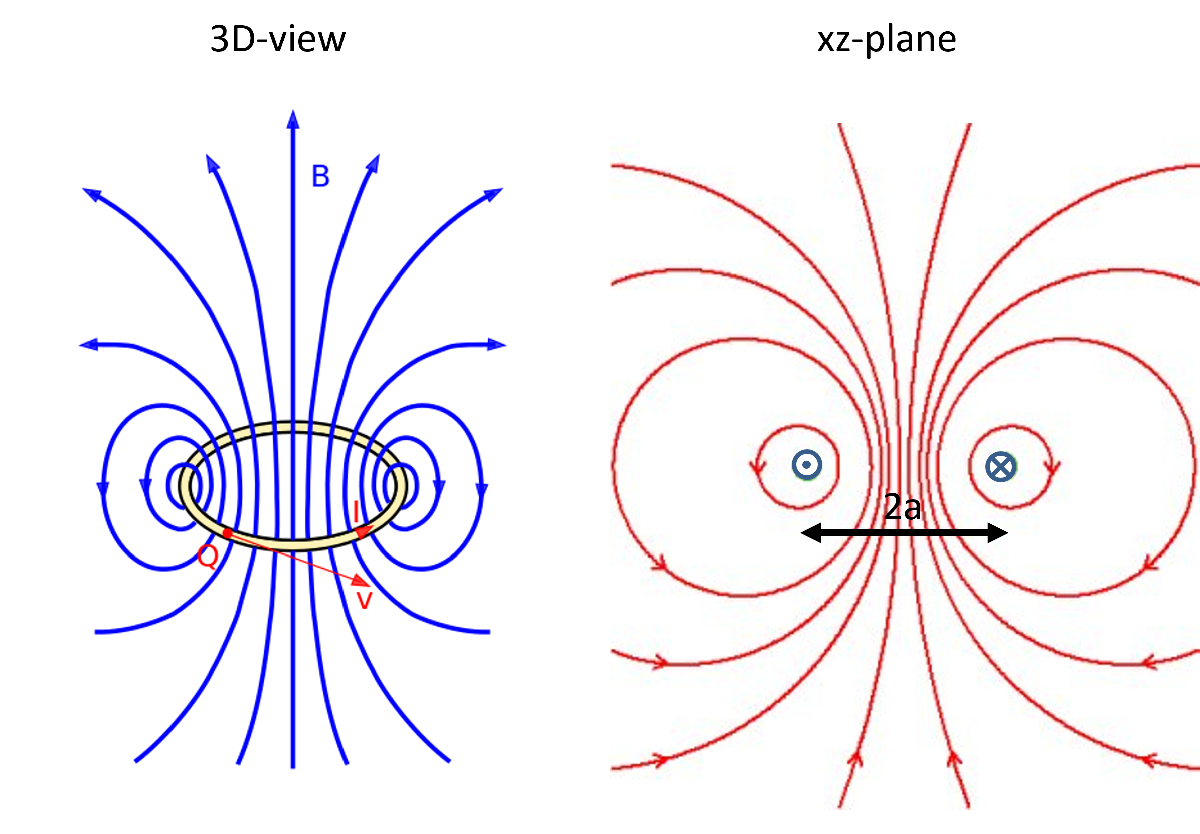

The x-component thus corresponds to the radial component r and the y-component to the azimuthal component phi.

clear,clc
syms phi a x I positive
syms z y real
rv=[x,0,z]';                 % field vector
sv=a*[cos(phi),sin(phi),0]'; % current vector
ds=diff(sv,phi);    

vector potential of a current loop ${\displaystyle {\mathbf {A}}({\mathbf {r}})={\frac {\mu _{0}I}{4\pi }}
\int \frac { d \mathbf s}{|{\mathbf {r}}-{\mathbf {s}}|}}
$

dA = simplify(I/(4*pi)*ds/norm(rv-sv));
A = int(dA,phi,0,2*pi)

$$A = \left(\begin{array}{c} 0\\ \int_{0}^{2\,\pi }\frac{\text{I}\,a\,\cos\left(\varphi \right)}{4\,\pi \,\sqrt{a^{2}-2\,\cos\left(\varphi \right)\,a\,x+x^{2}+z^{2}}}\mathrm{d}\varphi \\ 0 \end{array}\right)$$

Due to symmetry only $A_y = A_\varphi$  exists

dAy=simplify(dA(2));

This definite integral matlab cannot solve symbolically 

% int(dAy,phi,0,2*pi)

But matlab can solve the indefinite integral with respect to phi. 

Calculating the limits towards 0 and 2$\pi$ results in the solution for the vector potential of a current loop  

Ay0 = int(dAy,phi);
Ay=simplify(limit(Ay0,phi,2*pi)-limit(Ay0,phi,0),999)

$$Ay = \begin{array}{l} \frac{\text{I}\,\left(2\,K\left(-\frac{4\,a\,x}{\sigma_{1}}\right)\,\left(a^{2}+x^{2}+z^{2}\right)-2\,E\left(-\frac{4\,a\,x}{\sigma_{1}}\right)\,\sigma_{1}\right)}{4\,x\,\pi \,\sqrt{\sigma_{1}}}\\ \mathrm{where}\\ \sigma_{1}=a^{2}-2\,a\,x+x^{2}+z^{2} \end{array}$$

Long expressions can be simplified with subexpressions

Ay1=subexpr(Ay)

 
sigma = 
 


$$a^{2}-2\,a\,x+x^{2}+z^{2}$$

$$Ay1 = -\frac{\text{I}\,\left(2\,\sigma \,E\left(-\frac{4\,a\,x}{\sigma }\right)-2\,K\left(-\frac{4\,a\,x}{\sigma }\right)\,\left(a^{2}+x^{2}+z^{2}\right)\right)}{4\,\sqrt{\sigma }\,x\,\pi }$$

### Verification with the [published](https://ntrs.nasa.gov/archive/nasa/casi.ntrs.nasa.gov/20010038494.pdf) solution from James Simpson

% arbitrary parameters
I = 1;     % current
a = 1;     % radius
z = 1;     % z-coordinate
x = 1;     % x-coordinate

% Matlab symbolic solution
A = eval(Ay)

A = 0.0205

% formula from paper
r0=sqrt(x^2+z^2);
k2=4*a*r0*x/r0/(a^2+r0^2+2*a*r0*x/r0);
[K,E] = ellipke(k2);
A_paper=I*a/pi/sqrt(a^2+r0^2+2*a*r0*x/r0)*((2-k2)*K-2*E)/k2

A_paper = 0.0205

# Magnetic flux density from the vector potential

## a) matlab built-in curl operator in cartesian coordinates

syms phi a x I positive
syms z y real


$$\mathbf B = \nabla \times \mathbf A = \mathrm{rot} \mathbf A
$$


matlab calculates the curl operator in cartesian coordinates only 

$\rightarrow$vector [transform](https://de.wikipedia.org/wiki/Polarkoordinaten#Basisvektoren) $A_{\varphi} ~\textrm{ to }~ A_x  ~\textrm{ and}~A_y$:


$$A_x=-A_{\varphi} \sin(\varphi) 
\quad \textrm{ with} ~\sin(\varphi)= \frac y r
~\textrm{ and} ~r^2=x^2+y^2$$



$$A_y=A_{\varphi} \cos(\varphi) 
\quad ~\textrm{ with}~ \cos(\varphi)= \frac x r
~\textrm{ and } ~r^2=x^2+y^2$$


H=curl([-Ay*y/sqrt(y^2+x^2),Ay*x/sqrt(y^2+x^2),0],[x,y,z]);

Hx=simplify(subs(H(1),y,0))

$$Hx = \begin{array}{l} -\frac{\text{I}\,z\,\left(a^{2}\,K\left(\sigma_{1}\right)-a^{2}\,E\left(\sigma_{1}\right)-x^{2}\,E\left(\sigma_{1}\right)+x^{2}\,K\left(\sigma_{1}\right)-z^{2}\,E\left(\sigma_{1}\right)+z^{2}\,K\left(\sigma_{1}\right)+2\,a\,x\,K\left(\sigma_{1}\right)\right)}{2\,x\,\pi \,\sqrt{\sigma_{2}}\,\left(a^{2}+2\,a\,x+x^{2}+z^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=-\frac{4\,a\,x}{\sigma_{2}}\\ \sigma_{2}=a^{2}-2\,a\,x+x^{2}+z^{2} \end{array}$$

Hy=simplify(subs(H(2),y,0))

$$Hy = 0$$

Hz=simplify(subs(H(3),y,0))

$$Hz = \begin{array}{l} \frac{\text{I}\,\left(a^{2}\,\sigma_{2}+a^{2}\,\sigma_{1}-x^{2}\,\sigma_{2}+x^{2}\,\sigma_{1}-z^{2}\,\sigma_{2}+z^{2}\,\sigma_{1}+2\,a\,x\,\sigma_{1}\right)}{2\,\pi \,\sqrt{a^{2}-2\,a\,x+x^{2}+z^{2}}\,\left(a^{2}+2\,a\,x+x^{2}+z^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=K\left(-\frac{4\,a\,x}{a^{2}-2\,a\,x+x^{2}+z^{2}}\right)\\ \sigma_{2}=E\left(-\frac{4\,a\,x}{a^{2}-2\,a\,x+x^{2}+z^{2}}\right) \end{array}$$

#### simplify result on axis

Hz0 = subs(Hz,x,0)

$$Hz0 = \frac{\text{I}\,a^{2}}{2\,{\left(a^{2}+z^{2}\right)}^{3/2}}$$

#### verify off-axis solution with solution from problem 5a) 

% Parameter
I = 1;     % Strom
a = 1;     % Radius
z = 1;     % z-Koordinate
x = 1;     % x-Koordinate

Hr_num = eval(Hx) 

Hr_num = 0.0910

Hz_num = eval(Hz) 

Hz_num = 0.0768

## b) curl operator in cylindrical coordinates (Koordinatensysteme.pdf)

syms phi a x I positive
syms z y real

Hr = simplify(-diff(Ay,z),299)

$$Hr = \begin{array}{l} \frac{\text{I}\,z\,E\left(\sigma_{1}\right)}{\sigma_{2}}-\frac{\text{I}\,z\,K\left(\sigma_{1}\right)}{\sigma_{2}}-\frac{\text{I}\,a\,x\,z\,E\left(\sigma_{1}\right)}{\sqrt{a^{2}-2\,a\,x+x^{2}+z^{2}}\,\left(\pi \,a^{2}\,x+2\,\pi \,a\,x^{2}+\pi \,x^{3}+\pi \,x\,z^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=-\frac{4\,a\,x}{a^{2}-2\,a\,x+x^{2}+z^{2}}\\ \sigma_{2}=2\,x\,\pi \,\sqrt{a^{2}-2\,a\,x+x^{2}+z^{2}} \end{array}$$

Hz=simplify(diff(x*Ay,x)/x)

$$Hz = \begin{array}{l} \frac{\text{I}\,a^{2}\,E\left(\sigma_{1}\right)+\text{I}\,a^{2}\,K\left(\sigma_{1}\right)-\text{I}\,x^{2}\,E\left(\sigma_{1}\right)+\text{I}\,x^{2}\,K\left(\sigma_{1}\right)-\text{I}\,z^{2}\,E\left(\sigma_{1}\right)+\text{I}\,z^{2}\,K\left(\sigma_{1}\right)+2\,\text{I}\,a\,x\,K\left(\sigma_{1}\right)}{2\,\pi \,\sqrt{\sigma_{2}}\,\left(a^{2}+2\,a\,x+x^{2}+z^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=-\frac{4\,a\,x}{\sigma_{2}}\\ \sigma_{2}=a^{2}-2\,a\,x+x^{2}+z^{2} \end{array}$$

#### simplify result on axis

Hz0 = subs(Hz,x,0)

$$Hz0 = \frac{\text{I}\,a^{2}}{2\,{\left(a^{2}+z^{2}\right)}^{3/2}}$$

#### verify off-axis solution with solution from magnetic field problem 5a) 

% Parameter
I = 1;     % Strom
a = 1;     % Radius
z = 1;     % z-Koordinate
x = 1;     % x-Koordinate

Hr_num = eval(Hr) 

Hr_num = 0.0910

Hz_num = eval(Hz) 

Hz_num = 0.0768